# Plotting open source data from Muños-Royo et al. 2022 

#### 'Selfie' experiments: investigates the sediment plume in the wake of the vehicle.

- Vehicle drove for ~100m collecting nodules

- Turned off collector

- 3 x 90º turns

- drive through the collector plume perpendicularly across the track. 

*- Each selfie ecountered the plume at an earlier time in its life cycle than the previous.*

- Photo taken at intervals through the selfie

- Vertical sediment concentration profile taken using 'Seapoint Turbidity Meter'

#### Plot of sediment concentration across plume with varying heights, same distance behind collector

clear all
close all

%%% plot example selfie experiment
selfies = ["A1";"A2";"A3";"B1";"B2";"C1";"C2";"C3"];

% open the struct file for exp of your choice
experiment = selfies(8);
load('selfie/' + experiment + '.mat');

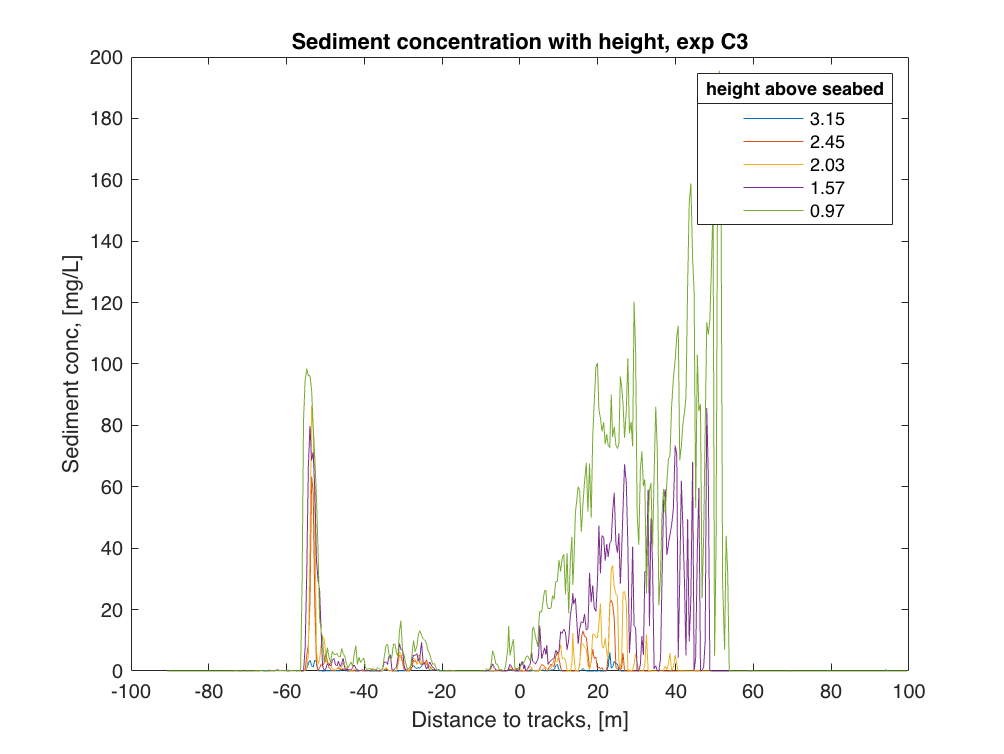

% plot sediment conc for given exp
figure(1)
plt = plot(dat_plot.distance_to_tracks, dat_plot.sediment_concentration);
leg = legend(string(dat_plot.height_above_seabed));
title(leg, 'height above seabed');
title('Sediment concentration with height, exp ' + experiment)
ylabel("Sediment conc, " + dat_plot.metadata.sediment_concentration_units)
xlabel("Distance to tracks, " + dat_plot.metadata.distance_to_tracks_units)
xlim([-100,100])

#### Plot of sediment concentration with distance behind collector, same height

clear all
close all

% experiment names
selfies = ["A1";"A2";"A3";"B1";"B2";"C1";"C2";"C3"];
load("height_above_seabed.mat");

%choose height to investigate
h = 1;
disp("Height = " + num2str(heights(h)) + ' m')

Height = 3.15 m


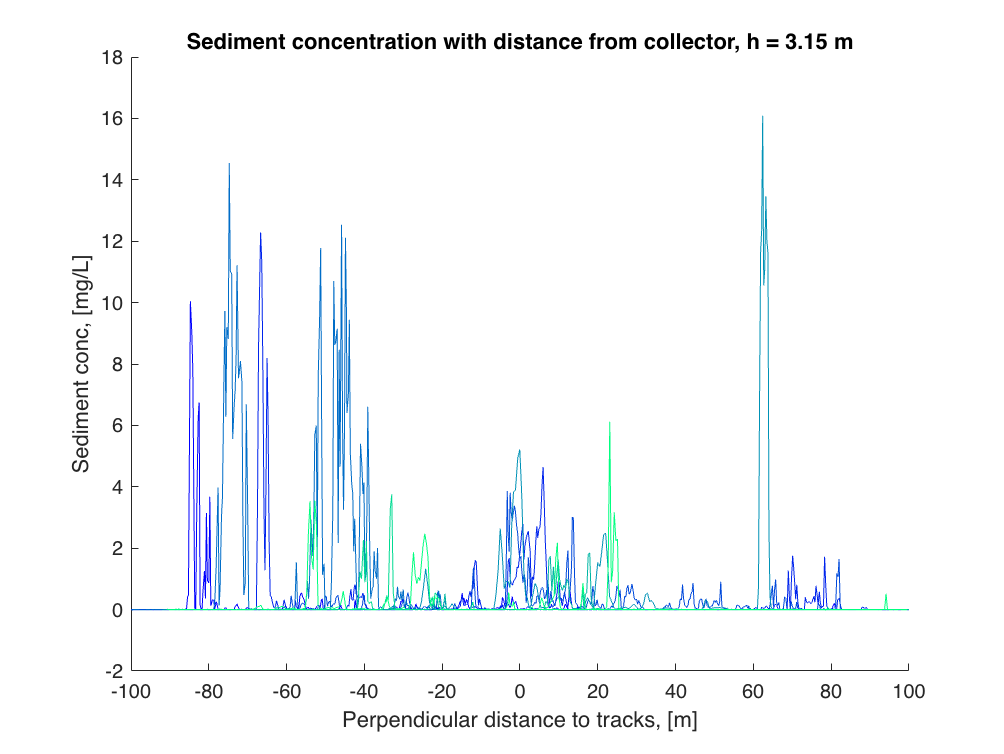


distance = zeros(900,8);
sed_conc = zeros(900,8);

% loop through the experiments
for e = 1:length(selfies)
        filename = (selfies(e) + '.mat');
        load(filename); % called dat_plot

        d = dat_plot.distance_to_tracks;
        sz_d = length(d);
        distance(1:sz_d,e) = d;
        clearvars d sz_d

        %only take sed conc at height we want to look at
        sc = dat_plot.sediment_concentration(:,h);
        sz_sc = length(sc);
        sed_conc(1:sz_sc,e) = sc;
        clearvars sc sz_sc 

    clearvars e filename
end

figure(2)
cm = winter(8);

for e = 1:length(selfies) % Each experiment
    hold on
    plot(distance(:,e), sed_conc(:,e), 'Color', cm(e,:));
end
hold off 

% add colour bar showing distance from collector

title("Sediment concentration with distance from collector, h = "+ num2str(heights(h)) + " m" )
ylabel("Sediment conc, " + dat_plot.metadata.sediment_concentration_units)
xlabel("Perpendicular distance to tracks, " + dat_plot.metadata.distance_to_tracks_units)
xlim([-100,100])

% better to make stacked subplots showing the change







